%% TD3 RADAR
% radard=load('radard.mat');
clear all;
close all;
clc

% GET TX AND RX SIGNAL
Radar_Tx_Signal = load('Radar_Tx_Signal.mat');
Radar_Rx_signal = canal_radar(Radar_Tx_Signal);

Bw_bruit = 5.0000e+10

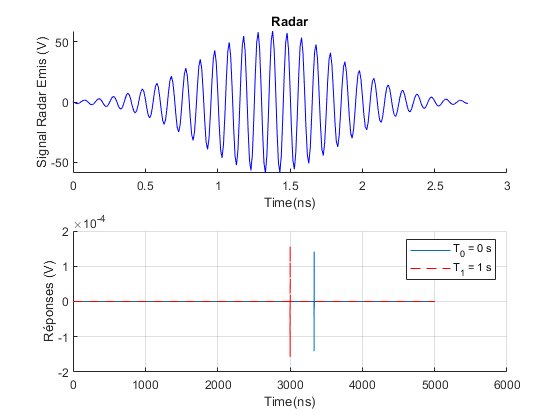


Reponse_0 = Radar_Tx_Signal.Tx_signal;
t0 = Radar_Tx_Signal.time_scale;
%
No_signal = Radar_Rx_signal.No_signal;
Reponse_1 = Radar_Rx_signal.Reponse_1;
Reponse_2 = Radar_Rx_signal.Reponse_2;
t = Radar_Rx_signal.t;

% AFFICHAGE
figure(1);
subplot(2,1,1)
hold on
plot(t0*1e9,Reponse_0,'b-')
title('Radar')
xlabel('Time(ns)')
ylabel('Signal Radar Emis (V)')
subplot(2,1,2)
hold on
plot(t*1e9,Reponse_1)
plot(t*1e9,Reponse_2,'r--')
legend('T_0 = 0 s', 'T_1 = 1 s')
xlabel('Time(ns)')
ylabel('Réponses (V)')
grid;

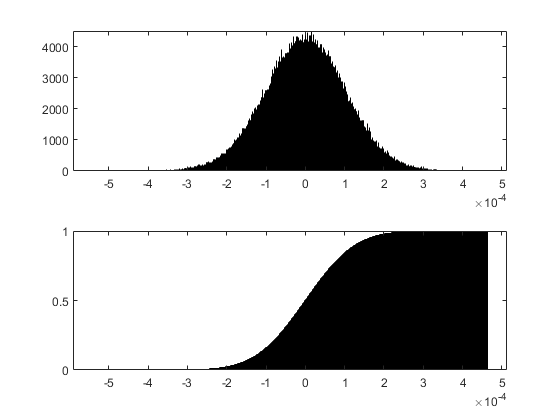


% Compute and plot distribution et stat cumulee
figure(2)
subplot(2,1,1);
histogram(No_signal, 5000, 'Normalization', 'pdf');
subplot(2,1,2);
histogram(No_signal, 5000, 'Normalization', 'cdf');

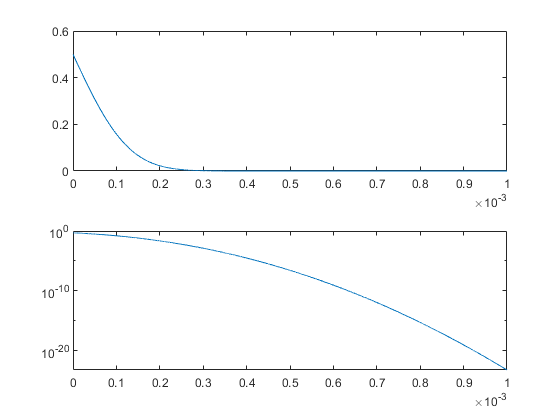


% Compute power
power = trapz(t, No_signal.^2) / t(Radar_Rx_signal.N);

% Compute stat variables
moyenne = mean(No_signal);
variance = var(No_signal);
ecart_type = sqrt(variance);

% Create Vseuil vector
V_seuil = 1e-7:1e-7:1e-3;

% Compute PFA(Vseuil)
PFA = erfc(V_seuil ./ (ecart_type * sqrt(2))) / 2;

% Plot FPA(Vseuil) 
figure(3)
subplot(2,1,1);
plot(V_seuil, PFA)
subplot(2,1,2);
semilogy(V_seuil, PFA)